1(c)

P_e = 10^-5;
corr = 0.2;

SNR_orth = (qfuncinv(P_e)^2)

SNR_orth = 18.1893

SNR_corr02 = (qfuncinv(P_e)^2)/(1-corr)

SNR_corr02 = 22.7366

2(d)

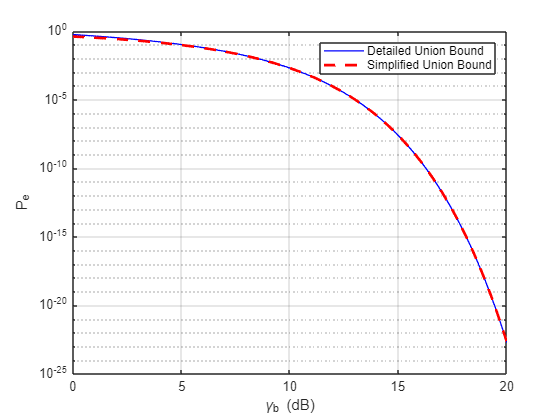

E0 = 1;
Eb = 2 * E0; % Energy per bit
M = 8; % Number of symbols
gamma_b_dB = 0:0.1:20; % SNR per bit in dB
gamma_b = 10.^(gamma_b_dB / 10); % SNR per bit on linear scale

% Distances and coefficient pairs
d_min = 2 * sqrt(E0);
d = [d_min, sqrt(2) * d_min, 2 * d_min, sqrt(5) * d_min, 3 * d_min, sqrt(10) * d_min];
a_k = [20, 12, 8, 8, 4, 4] ./M;
b_k = (d.^2) ./ (2 * Eb);

% Union bound
P_e_detailed = zeros(1, length(gamma_b));
for k = 1:length(a_k)
    P_e_detailed = P_e_detailed + a_k(k) * qfunc(sqrt(b_k(k) * gamma_b));
end

% Simplified bound
P_e_simplified = a_k(1) * qfunc(sqrt(b_k(1) * gamma_b));

% Plot
figure;
semilogy(gamma_b_dB, P_e_detailed, 'b', 'LineWidth', 1); hold on;
semilogy(gamma_b_dB, P_e_simplified, 'r--', 'LineWidth', 2);
grid on;
xlabel('\gamma_b (dB)');
ylabel('P_e');
legend('Detailed Union Bound', 'Simplified Union Bound');

6(d)

p_negTs = 0.02;
p_0 = -0.04;
p_Ts = 1.0;
p_2Ts = 0.06;
SNR_dB = 15; 

P_signal = p_Ts^2;
P_interference = p_negTs^2 + p_0^2 + p_2Ts^2;
P_noise = P_signal / 10^(SNR_dB / 10);

SIR = 10 * log10(P_signal / P_interference)

SIR = 22.5181

SINR = 10 * log10(P_signal / (P_interference + P_noise))

SINR = 14.2919